# Figure 3H

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A008_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 4×5 cell array
    {'siControl DMSO'}    {[  3]}    {[    3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siControl 4/6i'}    {[  3]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siCdh1 DMSO'   }    {[4 5]}    {[    3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCdh1 4/6i'   }    {[4 5]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

conds=[1 2];
timeGate = [0 20];
colors = [.1 .4 1; .6 .9 .2;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   
   inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)&...
         S(conds(i)).goodCdk;
sum(inds)
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 1416

ans = 62

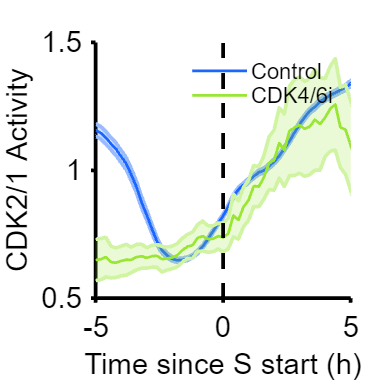


ylabel({'CDK2/1 Activity'});
xlabel('Time since S start (h)');
legend('Control','CDK4/6i','box','off','Location','northeast','fontsize',12);

xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')

% print_pdf(['fig_3Hleft.pdf'])

conds=[1 2];
timeGate = [0 20];
colors = [.1 .4 1; .6 .9 .2;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)&...
         S(conds(i)).goodCdk;
sum(inds)
    ydata = data.sigNuc(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 1416

ans = 62

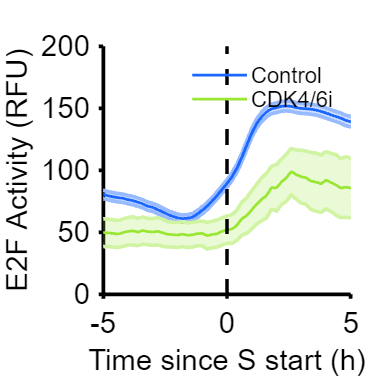


ylabel({'E2F Activity (RFU)'});
xlabel('Time since S start (h)');
legend('Control','CDK4/6i','box','off','Location','northeast','fontsize',12);

xlim([-5 5]); 
ylim([0 200]);
vline([0],'k--')

 % print_pdf(['fig_3Hright.pdf'])
